function [CoilInfoTableStruct,CoilTableStruct] =parsPhaseParaMCADTable(NewCellofWindingfTableByPhase,slotArray,LayerArray)
PhaseLength     =height(NewCellofWindingfTableByPhase);
ParallelNumber  =width(NewCellofWindingfTableByPhase);
CoilTableStruct         =cell(PhaseLength,ParallelNumber);
 % PhaseIndex=1
% ParallelIndex=1
for ParallelIndex=1:ParallelNumber

    for PhaseIndex=1:PhaseLength

    TargetTable         =NewCellofWindingfTableByPhase{PhaseIndex,ParallelIndex};
    

### Phase & ParaPath 별로 수행

### GoSlot'인 행 찾기

    % GoSlotRows = TargetTable(contains(TargetTable.TypeofData,'GoSlot'),:)
    % % 'GoSlot'인 행의 ValueTable 값 찾기
    % GoSlotValues = str2double(GoSlotRows.ValueTable);
    % uniqueGoSlot =unique(GoSlotValues);

###   'ReturnSlot'인 행 찾기

    % ReturnSlotRows = TargetTable(contains(TargetTable.TypeofData,'ReturnSlot'),:)
    % % 'GoSlot'인 행의 ValueTable 값 찾기
    % ReturnSlotValues = str2double(ReturnSlotRows.ValueTable);
    % uniqueReturnSlot =unique(ReturnSlotValues);


##  SlotLayer Table을 만들어놓고 Coil Index별로 데이터 넣기

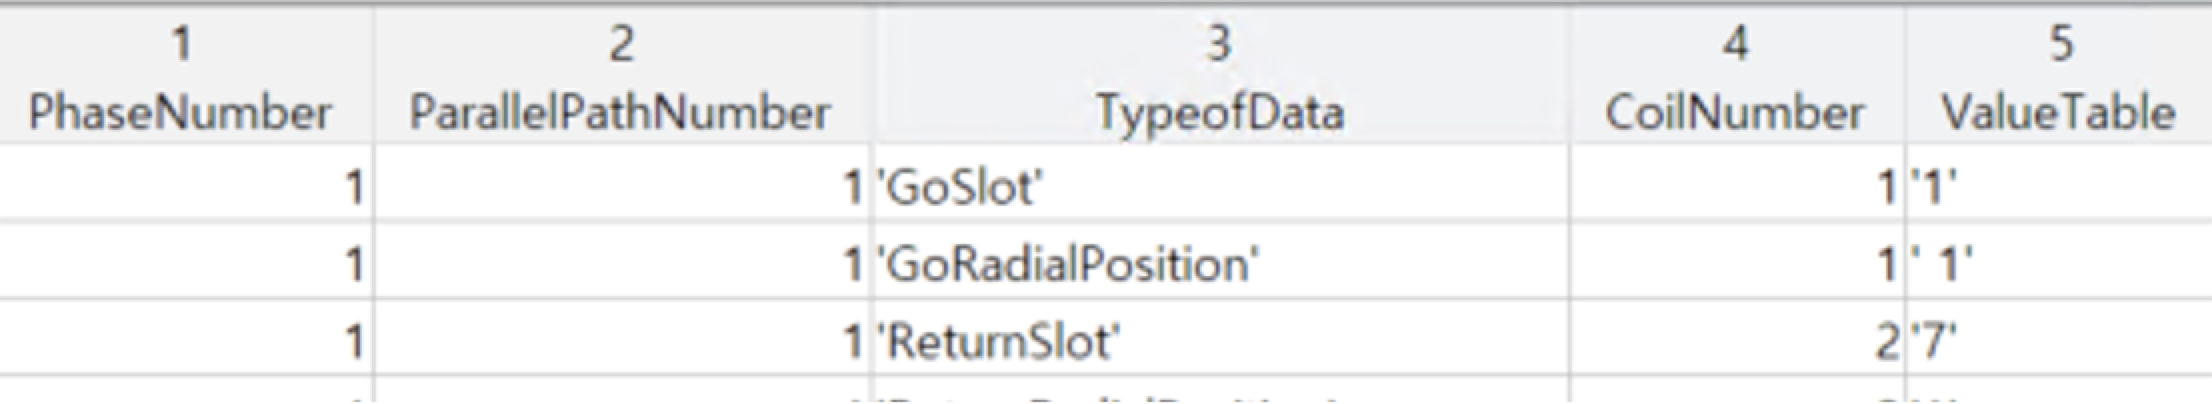

% 빈 SlotLayerTable만들기
CoilNumberTableBySlotLayer=mkSlotLayerTable(slotArray,LayerArray);
CoilInfoTable=mkCoilInfoTable(slotArray,PhaseIndex,ParallelIndex,length(LayerArray));

% mkSlotLayerDataCell
CoilNumber=max(NewCellofWindingfTableByPhase{PhaseIndex,ParallelIndex}.CoilNumber);
% Coil Number Index
for CoilNumberIndex=1:CoilNumber
    DataTableofCoilIndex=TargetTable(TargetTable.CoilNumber==CoilNumberIndex,["TypeofData","ValueTable"]);
    SlotIndex=DataTableofCoilIndex.ValueTable{contains(DataTableofCoilIndex.TypeofData,'Slot')};
    SlotIndex=str2double(SlotIndex);
    LayerIndex=DataTableofCoilIndex.ValueTable{contains(DataTableofCoilIndex.TypeofData,'Position')};
    LayerIndex=str2double(LayerIndex);
    CoilNumberName=num2str(CoilNumberIndex);
    CoilNumberTableBySlotLayer(LayerIndex,SlotIndex)=cellstr(CoilNumberName);
end

CoilInfoTableStruct{PhaseIndex,ParallelIndex} =CoilInfoTable;
CoilTableStruct{PhaseIndex,ParallelIndex}=CoilNumberTableBySlotLayer;
    end
end
% 
% % Coil Number  로 parsing
% TargetTable(contains(TargetTable.TypeofData,'GoRadialPosition'),"ValueTable")
% 
% matchingCoils = TargetTable.CoilNumber(ismember(TargetTable.ValueTable, GoSlotValues));
% matchingCoils = T.CoilNumber(ismember(T.ValueTable, goSlotValues));
% 
% 
%  % 같은 ValueTable 값을 가지는 모든 행의 CoilNumber 추출
% Go    % CoilNumber, GoSlot의  
% GoRadialPosition= TargetTable(contains(TargetTable.TypeofData,'GoRadialPosition'),:)
% GoRadialPosition = sortrows(GoRadialPosition,"ValueTable","ascend");
% GoRadialPosition.Properties.VariableNames(5)="LayerNumber"
% 
% 
% matchingCoils = TargetTable.CoilNumber(ismember(TargetTable.ValueTable, ));
% 
% GoRadialPosLayerFromValueTable=
% Stack CoilNumberTableBySlotLayer 2 SlotLayerCSVTableRadialPosition = zeros(height(TargetTable), 1); % 미리 GoRadialPosition 열을 0으로 초기화합니다.
    % matchingCoils = TargetTable.CoilNumber(ismember(TargetTable.ValueTable, '9'));
    % ReturnSlot의 CoilNumber와 동일한 Coil Number를 갖는 Layer의 Value
    % GoSlot의 CoilNumber와 동일한 Coil Number를 갖는 Layer
    % matchingCoils = T.CoilNumber(ismember(T.ValueTable, goSlotValues));
    % 
    % for LayerIndex=1:length(LayerArray)
    %     % GoSlot이면서 ra
    %     Phase1(ParallelPathNumber).LayerSlotStruct(LayerIndex).GotSlotTable=Phase1Table(contains(Phase1Table.TypeofData,'GoSlot'),["ParallelPathNumber","ValueTable","CoilNumber"])    
    % end

end
